# Import Building Information Model for Heat Load Analysis

## Import BIM Data

### 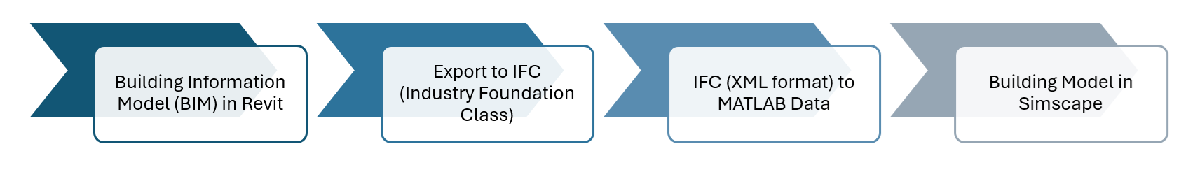

There are multiple 3D modelling CAD packages you can use to make a Building Information Model (BIM). This example uses the Autodesk Revit tool to generate the BIM, which you can export to a standard IFC format that stores data in an XML format. Import the XML data to Simscape with the utility function, `getBuildingDataFromBIM`, and create the Simscape building using `createBuildingModelFromBIM`.

There are 4 pre-generated building models in this project for this example. All the data is saved as XML files, along with their 3D snapshots, in the `Workflow/ImportBIMforHeatLoadAnalysis` folder.

The `getBuildingDataFromBIM` extracts only the geometry and material property data from the BIM model, which is the only data needed to create a Simscape Building. The solar load data based on the building location is automatically calculated within Simscape building component.

### Read Data

Read BIM data for a building that has two rooms: one a T-shaped room and the other a rectangular room.

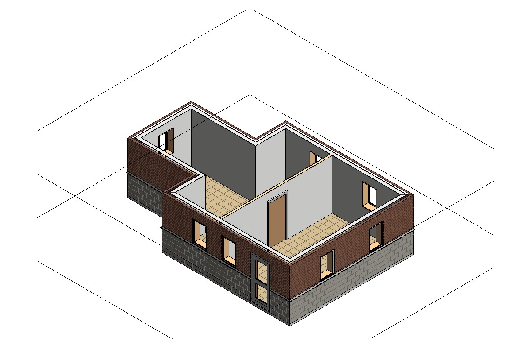

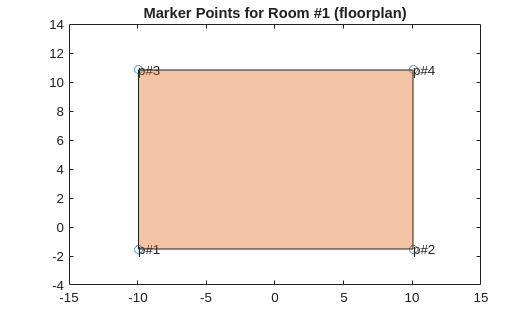

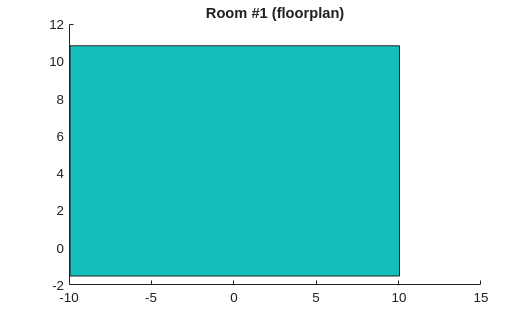

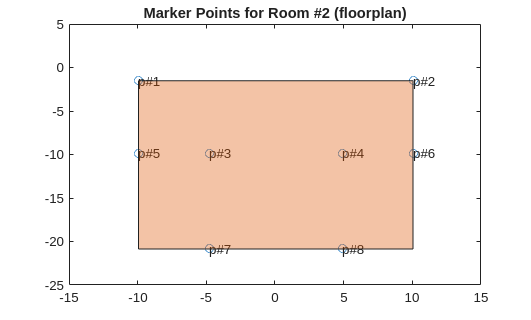

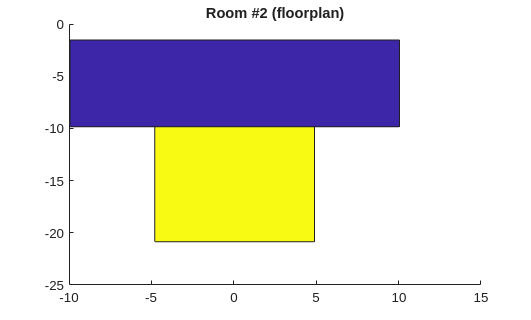

[modelData,dataBIM] = getBuildingDataFromBIM(...
                        FileName="importBuildingTshapedAndRectRoom.xml",...
                        Debug=false,RoundOff=5);

The output of the `getBuildingDataFromBIM` function displays some room connectivity information in a table, which specifies the room to room connectivity information. In Simscape, all rooms are specified as rectanglar. Non-rectangular rooms are made from a combination of multiple rectangular rooms, with connecting walls removed of modified. For example, in a T-shaped room, the room is represented by two rectangular rooms, both named with similar indices (room2a and room2b, in this case). The table shows that the connecting wall between these two rooms is missing, because the **Solid Wall Fraction **parameter is zero. The function automatically sets this data, and displays the table for information and data verification. You can also set the *Debug* argument in `getBuildingDataFromBIM` to *true* to read more diagnostics on the BIM data import process. 

### Create Building Model

Compute the data required to create building model in Simscape and save it in a data struct called `building`.

[building,modelData] = createBuildingModelFromBIM(...
                        DataBIM=dataBIM,...
                        DataBuilding=modelData,...
                        Debug=false,...
                        Tol=0.05,...
                        BuildingName="MyBuilding");

    #A     RoomA      #B     RoomB      Solid Wall Fraction
    __    ________    __    ________    ___________________

    1     "room1"     2     "room2a"          0.87953      
    2     "room2a"    3     "room2b"            0.001      



### Visualize Building Model

Visualize the Simscape `building` model. You can compare the visualization to the 3D snapshot above to confirm the model generation. In the Simscape building model, all walls and doors on a given wall are specified as a single opening. You may observe multiple windows on a given wall in the 3D representation, but would observe only a single opening in the Simscape representation. To learn more about the Simscape building model, see [Custom Block: Building Model](matlab:open('../Overview/html/DocumentationCustomBlockBuilding.html')) and [Room Modelling Options in Building Custom Component](matlab:open('../Overview/html/DocumentationRoomModellingOptions.html')).

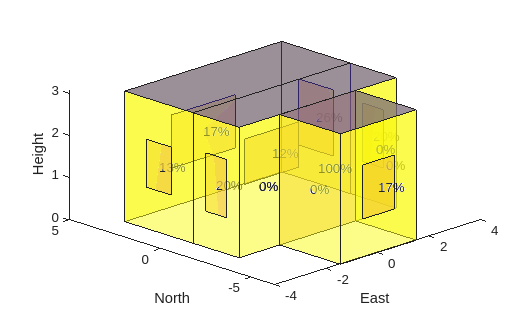

viewingAngle = [-1 -1 1]; 

figure("Name","BuildingUnit Elevation");
plot3DlayoutBuilding(Building=building,...
                        PlotViewDirection=viewingAngle,...
                        ColorScheme="simple",...
                        InternalWalls=true,...
                        DebugMode=true);

The 3D data is now ready to be modelled in Simscape. The workflow below is similar to the other workflows in this project (see [Building Heat Load Estimation](matlab:open('./BuildingHeatLoadEstimation.mlx')), [Building Management System Requirement Analysis,](matlab:open('./BuildingManagementSystemRequirementAnalysis.mlx')) [Simulate Building Energy Management System](matlab:open('./SimulateBuildingEnergyManagement.mlx'))).

## Add Solar Load to Building

Set building location and the time period. Add the solar load to the building model definition.

locationName = "Vienna";
geoLocation = getGeoLocationForMajorCities(CityName=locationName);

[building3D,dateTimeVec] = addSolarLoadToBuilding(...
                        Building=building,...
                        Location=geoLocation,...
                        StartTime=datetime(2024,1,1,1,0,0),...
                        EndTime=datetime(2024,12,31,1,0,0));

## Specify Ambient Conditions

Specify the monthly average temperature variation at the location.

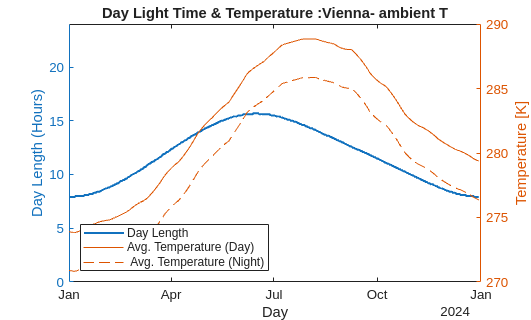

monthlyTavg = simscape.Value([269,275; 271 277; 273 282; ... % Q1 months (min,max)
                              277 287; 282 293; 286 296; ... % Q2 months (min,max)
                              287 297; 287 297; 283 292; ... % Q3 months (min,max)
                              279 287; 275 280; 270 275],... % Q4 months (min,max)
                              "K");

[ambient.AvgDayT,...
 ambient.AvgDayTvar,...
 ambient.AvgNightT,...
 ambient.AvgNightTvar] = getTemperatureFromYearlyData(...
                        DateTimeVec=dateTimeVec,...
                        Tavg12MonthData=monthlyTavg,...
                        DeltaDegreesNightT=simscape.Value(3,"K"),...
                        Plot=true,PlotName=strcat(locationName,"- ambient T"),...
                        Location=geoLocation,...
                        PercentDayTimeTvar=1,...
                        PercentNightTimeTvar=1);

## Parameterize Model for Energy Analysis

### Specify Operational Parameters

Initialize parameters for the building analysis. Building physics and operational information is stored in the parameters `physTable` and `opsParams`, respectively.

[physTable,opsParams] = initializeBuildingSimulationParameters(...
                        Building=building3D,...
                        DateTimeVec=dateTimeVec,...
                        Location=geoLocation,...
                        GroundResistance=simscape.Value(100,"K/W"),...
                        RoomTsetPoint=simscape.Value(293,"K"),...
                        HeatLoadPerPerson=simscape.Value(50,"W"),...
                        DayTemperature=ambient.AvgDayT,...
                        DayTemperatureVar=ambient.AvgDayTvar,...
                        NightTemperature=ambient.AvgNightT,...
                        NightTemperatureVar=ambient.AvgNightTvar);
            
[listOfRoomNames,listOfFloorLvls] = getAllRoomNameForBuilding(Building=building3D);


Apply 24hr room occupancy data to all rooms for all days specified by the datetime vector, `datetimeVec`.

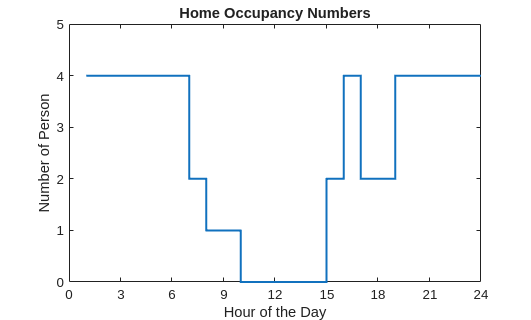

occupancyRate = set24HourRoomOccupancyNumber(...
                        OccupancyNumbers=[4 4 4 4 4 4 ... % 00:00 - 06:00 Hrs
                                          2 1 1 0 0 0 ... % 06:00 - 12:00 Hrs
                                          0 0 2 4 2 2 ... % 12:00 - 18:00 Hrs
                                          4 4 4 4 4 4],...% 18:00 - 24:00 Hrs
                        Plot=true);


physTable = apply24HrsDataForAllDaysToBuildingPhysics(...
                        Building=building3D,...
                        Data=occupancyRate,...
                        DateTimeVec=dateTimeVec,...
                        ListOfFloorLevels=unique(listOfFloorLvls)',...
                        ListOfRoomNames=unique(listOfRoomNames)',...
                        PhysicsParameter="Room Occupancy Level",...
                        PhysicsTable=physTable);

clear listOfRoomName listOfFloorLvls occupancyRate locationName building

### Specify HVAC

Set the HVAC model to be `alwaysON`. When you set the model to `adaptive,` the HVAC turns off when there are no occupants in a room.

physTable = editHVACBasedOnRoomOccupancyBuildingPhysics(...
                        PhysicsTable=physTable,...
                        HVAC="alwaysON");

### Specify Material Properties

Initialize the material property table.

materialDataTable = updateBuildingMaterialCompositeWallProp(...
                        CompositeExternalWall=modelData.WallMaterial.Data.ExteriorWall,...
                        CompositeInternalWall=modelData.WallMaterial.Data.InteriorWall,...
                        CompositeFloor=modelData.WallMaterial.Data.SlabOnGrade,...
                        CompositeRoof=modelData.WallMaterial.Data.Roof,...
                        WindowTransmissivity=modelData.WindowProperty.Transmittance);

*** You must not specify values marked as NaN in the table.
*** Block default values are provided where name-value-pair are not defined.
                                    Roof    Floor    ExternalWall    InternalWall    Window
                                    ____    _____    ____________    ____________    ______

    Absorptivity [-]                 0.6     NaN          0.6             NaN          0.4 
    Transmissivity [-]               NaN     NaN          NaN             NaN          0.2 
    Thickness [m]                    0.3     0.3          0.3             0.3         0.01 
    Density [kg/m^3]                2400    2400         2400            2400         4000 
    Heat Capacity [J/kg-K]           750     750       

### Parameterize Model

Combine all building modeling data into a single data struct.

buildingNetwork = getParamsForSimscapeComponent(...
                        Building=building3D,...
                        PhysicsTableData=physTable,...
                        OperationalData=opsParams);


Parameterize the building custom component in Simscape model.

mdl = setParametersForBuildingCustomComponent(...
                        Building=building3D,...
                        BuildingNetworkData=buildingNetwork,...
                        RoomModel="Thermal Requirements",...
                        Duration=dateTimeVec,...
                        ExternalHTC=simscape.Value(50,"W/(K*m^2)"),...
                        InternalHTC=simscape.Value(50,"W/(K*m^2)"),...
                        BuildingMaterial=materialDataTable);

Parameterized Model :BuildingModelWithSolarLoad.slx
*** Simulation Time = 8760-hours
*** Model Parameterized for Time =8761-hours
*** Solver :Fixed-step (ode1be)


## Simulate and Visualize Results

Simulate the building model.

result.Sim = sim(mdl);

Plot monthly averaged heating and cooling requirements.

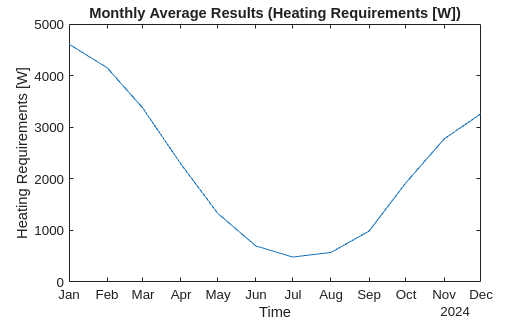

       Time         data 
    ___________    ______

    01-Jan-2024    4610.6
    01-Feb-2024    4152.8
    01-Mar-2024    3370.2
    01-Apr-2024    2286.4
    01-May-2024    1328.4
    01-Jun-2024    698.02
    01-Jul-2024    483.86
    01-Aug-2024    572.39
    01-Sep-2024     987.4
    01-Oct-2024    1925.2
    01-Nov-2024    2772.1
    01-Dec-2024    3261.9



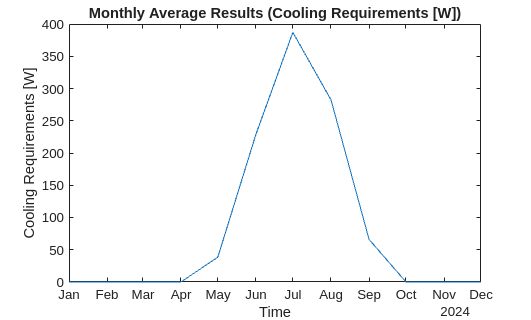

       Time          data  
    ___________    ________

    01-Jan-2024           0
    01-Feb-2024           0
    01-Mar-2024           0
    01-Apr-2024    0.082948
    01-May-2024      38.514
    01-Jun-2024      228.96
    01-Jul-2024      387.11
    01-Aug-2024      282.58
    01-Sep-2024      65.969
    01-Oct-2024           0
    01-Nov-2024           0
    01-Dec-2024           0



if exist("result","var")
    result.Q = result.Sim.simlog.Building.S.series.values;
    result.Q = sum(result.Q,2)'; 
    result.Qh = result.Q.*(result.Q>0);
    result.Qc = abs(result.Q.*(result.Q<0));
    result.t = result.Sim.simlog.Building.S.series.time;
    getMonthlyAveragedData(...
                         DateTimeVec=dateTimeVec,...
                         Data=result.Qh,...
                         Plot=true,...
                         PlotName="Heating Requirements [W]",...
                         DisplayData=true);
    getMonthlyAveragedData(...
                         DateTimeVec=dateTimeVec,...
                         Data=result.Qc,...
                         Plot=true,...
                         PlotName="Cooling Requirements [W]",...
                         DisplayData=true);
end